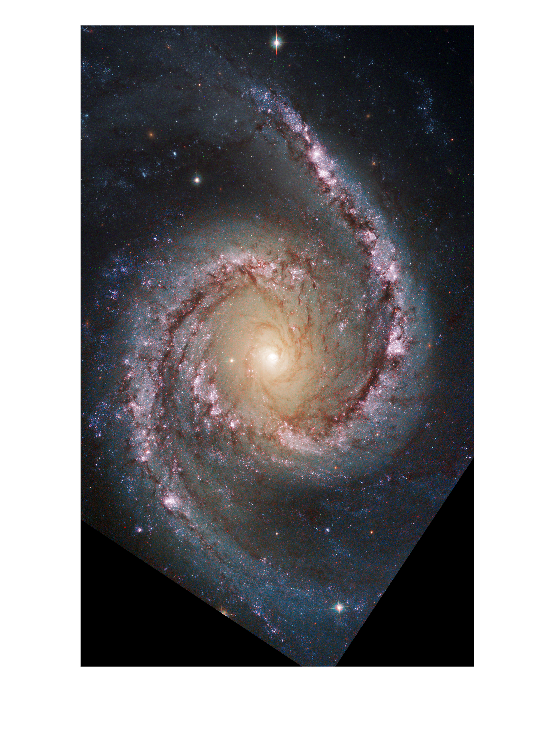

img = imread("D:\Nirma Assignments\IP\SpiralGalaxy.tif");
imshow(img);

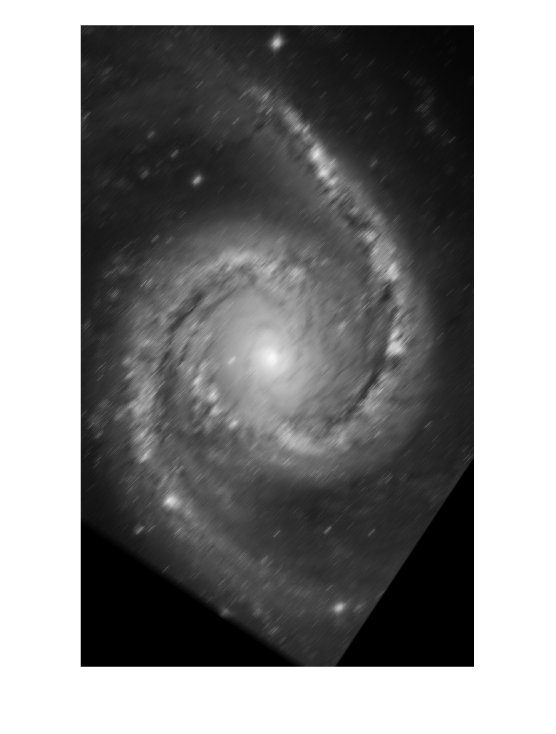

gray = im2gray(img);

mb = fspecial('motion', 50 ,45);
filterimg = imfilter(gray,mb,'replicate');
imshow(filterimg);

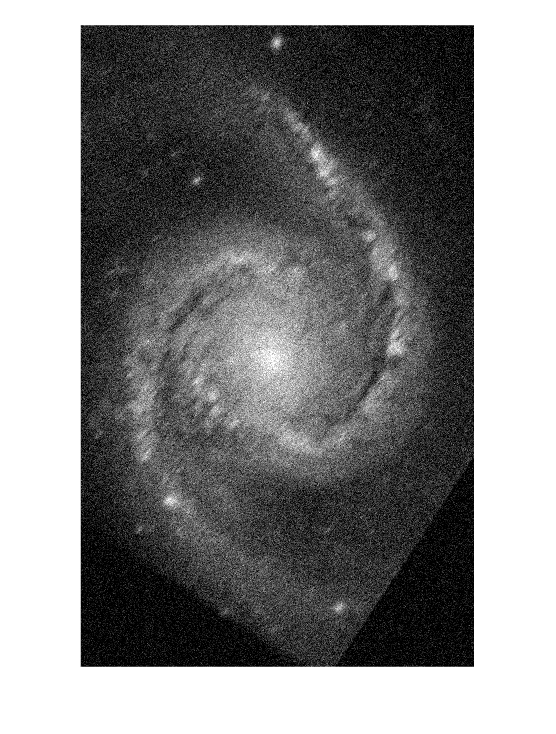

noiseimg = imnoise(filterimg,'gaussian');
imshow(noiseimg);

G = fft2(noiseimg);

H = fft2(mb, size(noiseimg, 1), size(noiseimg, 2));

% Regularization parameter (adjust if necessary)
K = 2;

% Apply regularized inverse filter
F_hat = (conj(H) ./ (abs(H).^2 + K)) .* G;

% Convert back to spatial domain
restored_img = real(ifft2(F_hat));
restored_img = mat2gray(restored_img); % Normalize for display

% Display the restored image
figure;
imshow(restored_img);